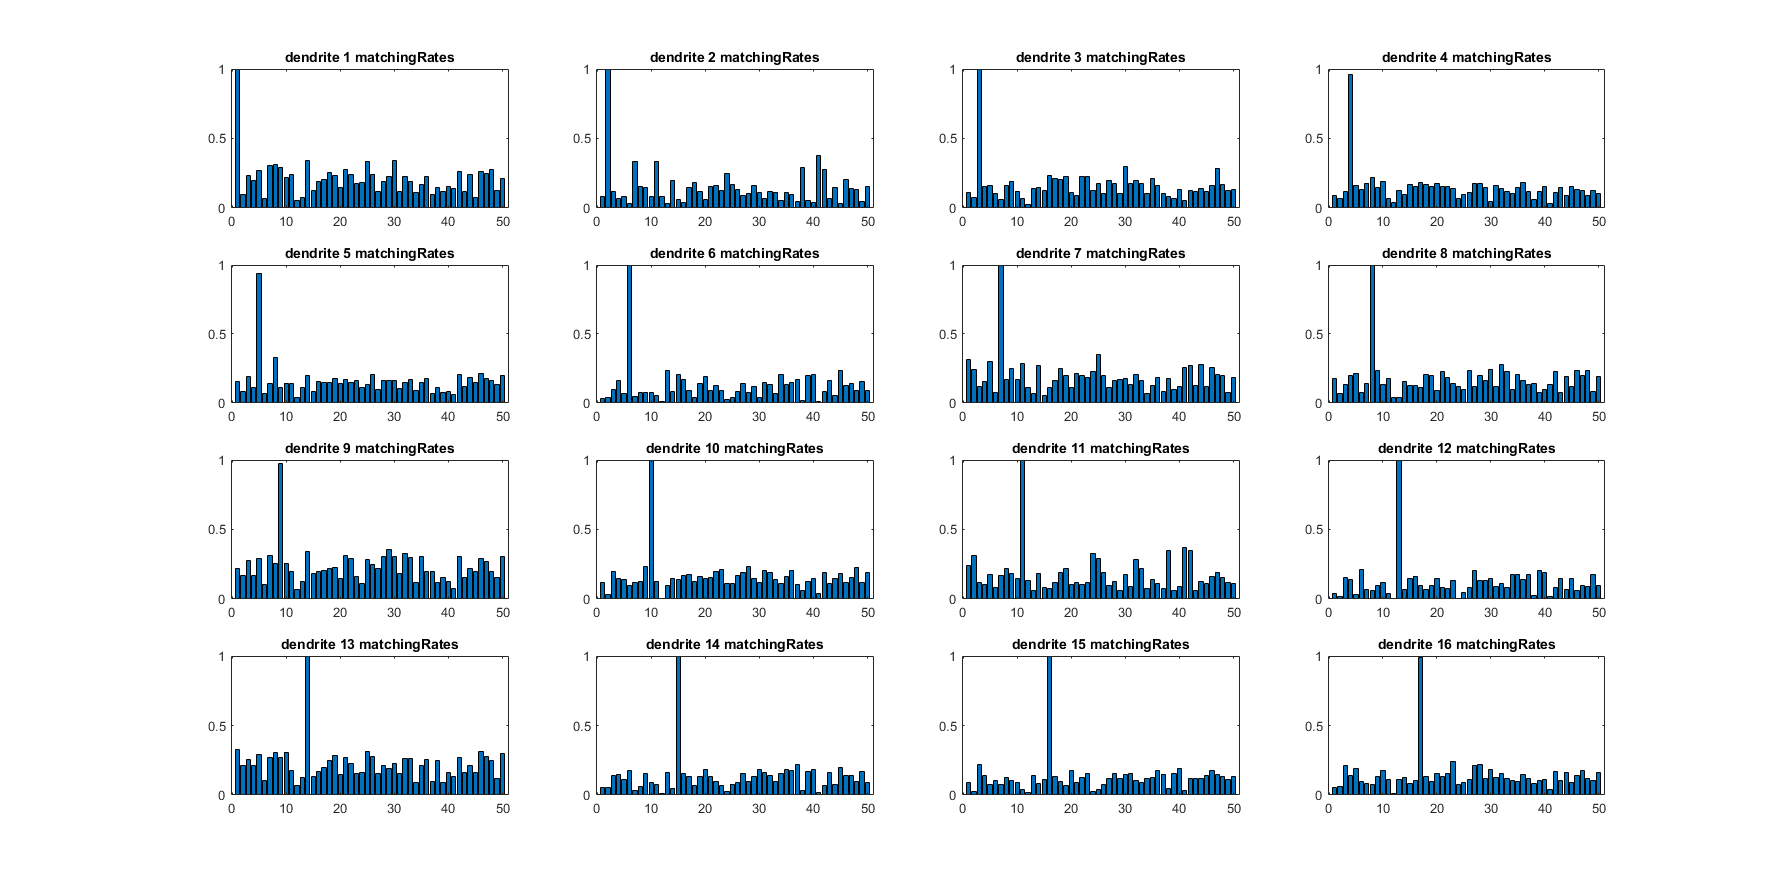

temp = 0;
for index = 1:17
    if index == 12
        continue
    end
    temp = temp + 1;
    eval(['load impuf50x50compareResult' num2str(index) '.mat']);
    subplot(4,4,temp)
    bar(Rmat)
    eval(['title ("dendrite ' num2str(temp) ' matchingRates")']);
end

load refIMG.mat
load testIMG.mat
[matchingRate, exactCorrectNum, iter_mat] = algfixTesting(testIMG, refIMG)

Center1 at [400, 400], radius = 3.450000e+01
Center1 at [400, 400], radius = 3.450000e+01


plot(iter_mat)
title('similiar dendrite 1 (iteration times vs matchingRate)')